X=randn(1,100)*10+50

X =    61.9810   61.9684   49.0262   56.1435   37.8140   55.7187   48.7169   66.0852   40.4293   70.1151   50.2008   54.4551   64.4953   61.0295   41.2414   40.8476   40.8518   60.7475   48.6430   45.5529   50.8252   60.3577   48.4111   53.0928   26.8460   43.3242   39.3341   43.6084   42.3803   45.7789   45.0867   56.5775   64.3608   34.6497   67.5284   62.8305   50.9364   65.8010   52.4478   39.7975   61.2784   72.3247   42.2575   39.9854   61.3833   49.7605   36.3617   62.3632   48.4592   42.0479


bin=[1:20:100]

bin =      1    21    41    61    81



X(20:20:100)=NaN

X =    61.9810   61.9684   49.0262   56.1435   37.8140   55.7187   48.7169   66.0852   40.4293   70.1151   50.2008   54.4551   64.4953   61.0295   41.2414   40.8476   40.8518   60.7475   48.6430       NaN   50.8252   60.3577   48.4111   53.0928   26.8460   43.3242   39.3341   43.6084   42.3803   45.7789   45.0867   56.5775   64.3608   34.6497   67.5284   62.8305   50.9364   65.8010   52.4478       NaN   61.2784   72.3247   42.2575   39.9854   61.3833   49.7605   36.3617   62.3632   48.4592   42.0479


X([1,7,56,87])=[7,10,90,70]

X =     7.0000   61.9684   49.0262   56.1435   37.8140   55.7187   10.0000   66.0852   40.4293   70.1151   50.2008   54.4551   64.4953   61.0295   41.2414   40.8476   40.8518   60.7475   48.6430       NaN   50.8252   60.3577   48.4111   53.0928   26.8460   43.3242   39.3341   43.6084   42.3803   45.7789   45.0867   56.5775   64.3608   34.6497   67.5284   62.8305   50.9364   65.8010   52.4478       NaN   61.2784   72.3247   42.2575   39.9854   61.3833   49.7605   36.3617   62.3632   48.4592   42.0479


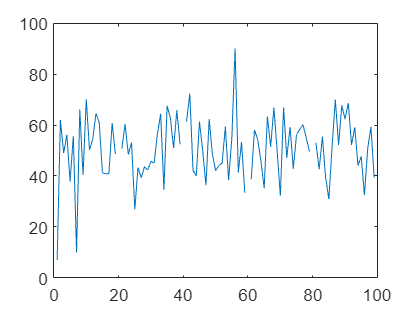


plot(X)

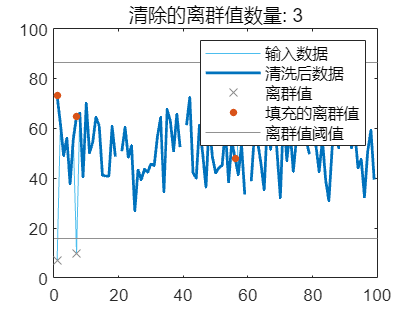

% 填充离群值
[X1,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(X, ...
    "makima","quartiles");

% 显示结果
figure
plot(X,"SeriesIndex",6,"DisplayName","输入数据")
hold on
plot(X1,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","清洗后数据")

% 绘制离群值
plot(find(outlierIndices),X(outlierIndices),"x","Color",[145 145 145]/255, ...
    "DisplayName","离群值")

% 绘制填充的离群值
plot(find(outlierIndices),X1(outlierIndices),".","MarkerSize",12, ...
    "SeriesIndex",2,"DisplayName","填充的离群值")

% 绘制离群值阈值
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]], ...
    "Color",[145 145 145]/255,"DisplayName","离群值阈值")

hold off
title("清除的离群值数量: " + nnz(outlierIndices))
legend

clear thresholdLow thresholdHigh

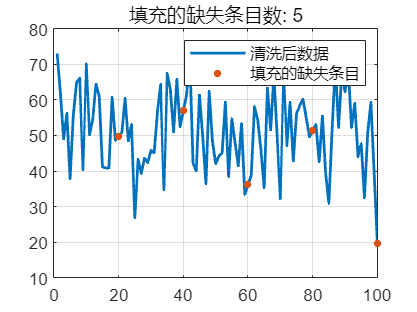

% 填充缺失数据
[X2,missingIndices] = fillmissing(X1,"linear");

% 显示结果
figure

% 绘制清洗后的数据
plot(X2,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","清洗后数据")
hold on

% 绘制填充的缺失条目
plot(find(missingIndices),X2(missingIndices),".","MarkerSize",12, ...
    "SeriesIndex",2,"DisplayName","填充的缺失条目")
title("填充的缺失条目数: " + nnz(missingIndices))

hold off
legend
clear missingIndices
grid on